### Exercise 7

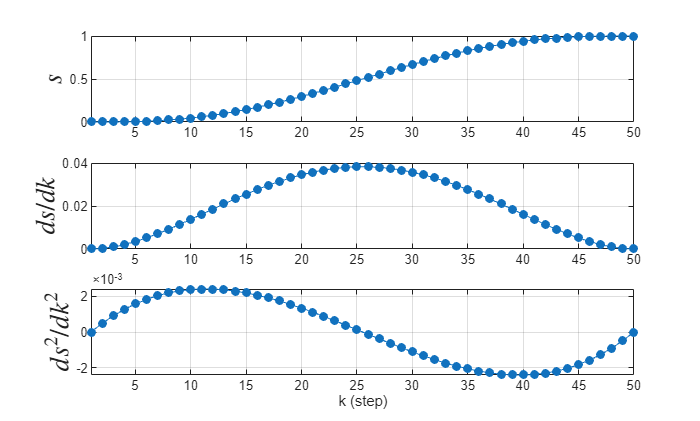

tpoly(0, 1, 50);

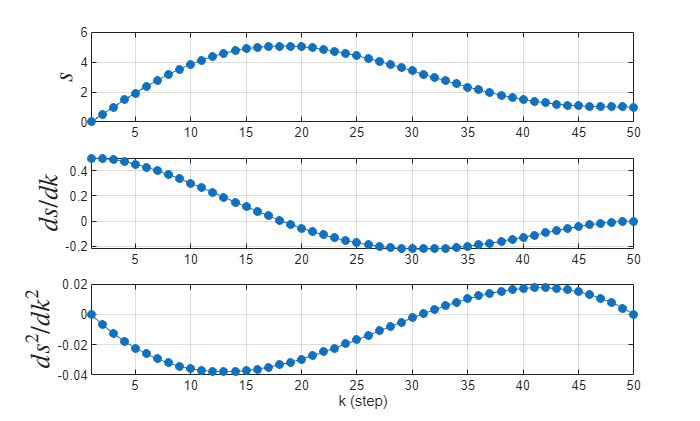

[s,sd,sdd] = tpoly(0, 1, 50);



tpoly(0, 1, 50, 0.5, 0);

v_i=0.5, v_f=0

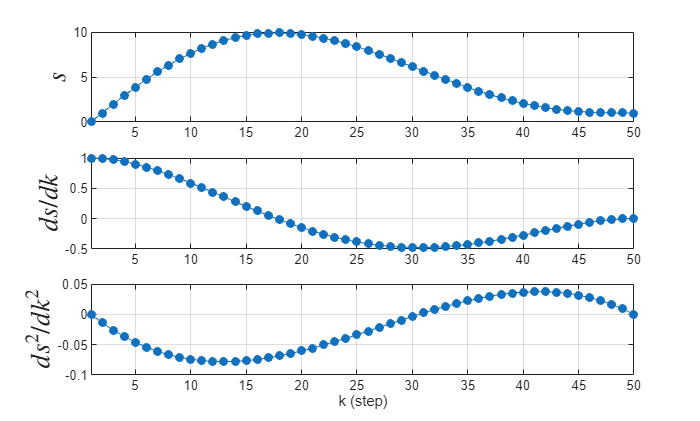

tpoly(0, 1, 50, 1, 0);

v_i=1, v_f=0

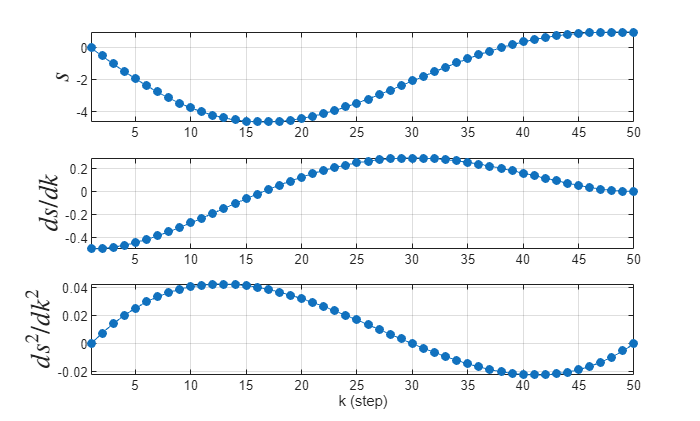

tpoly(0, 1, 50, -0.5, 0);

v_i=-0.5, v_f=0

### Exersice 8

mean(sd) / max(sd)

ans = 0.5000

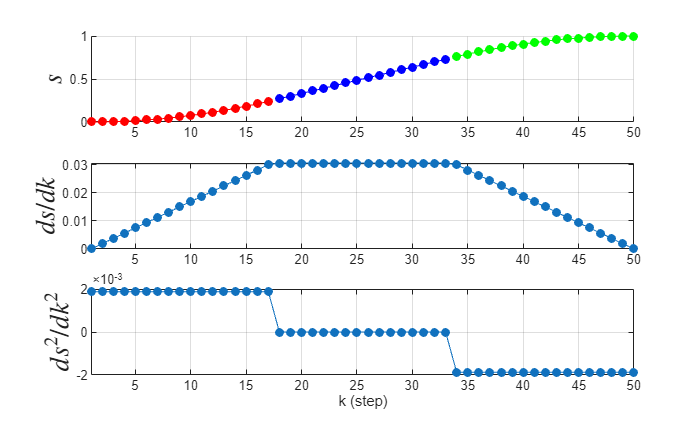



lspb(0, 1, 50);

[s,sd,sdd] = lspb(0, 1, 50);
max(sd)

ans = 0.0306

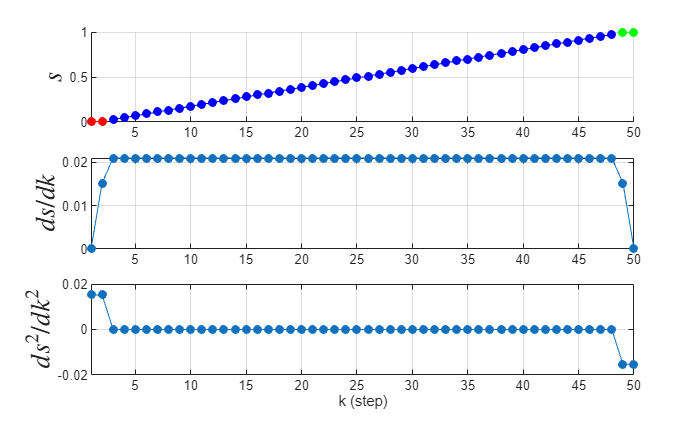

lspb(0, 1, 50, 0.021)

[s,sd,sdd]=lspb(0, 1, 50, 0.021);
max(sd)

ans = 0.0210

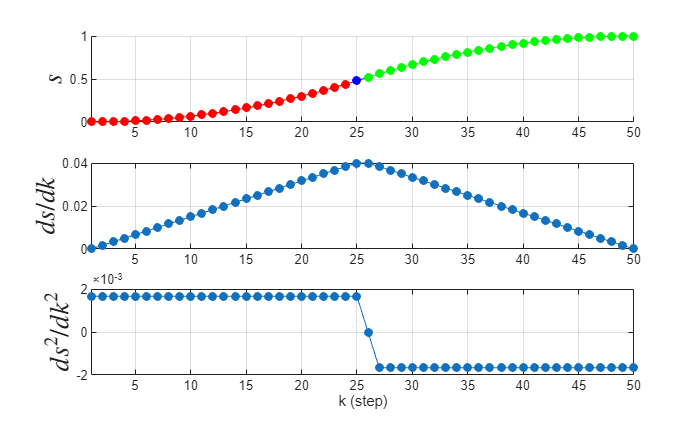

lspb(0, 1, 50, 0.040)

[s,sd,sdd]=lspb(0, 1, 50, 0.040);
max(sd)

ans = 0.0400

### Exersice 9

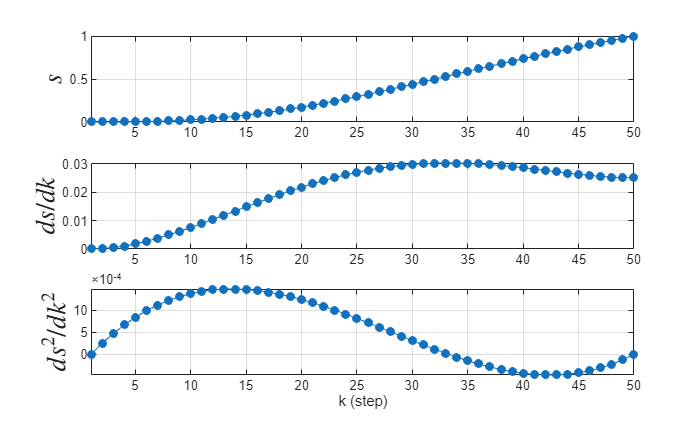

tpoly(0, 1, 50, 0, 0.025);

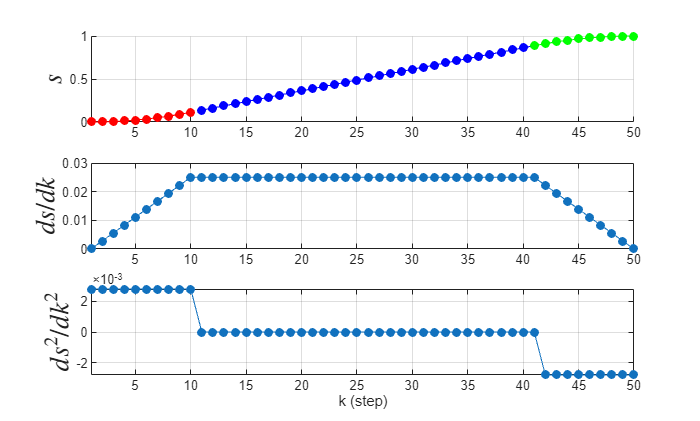

lspb(0, 1, 50, 0.025);

### Exersice 13

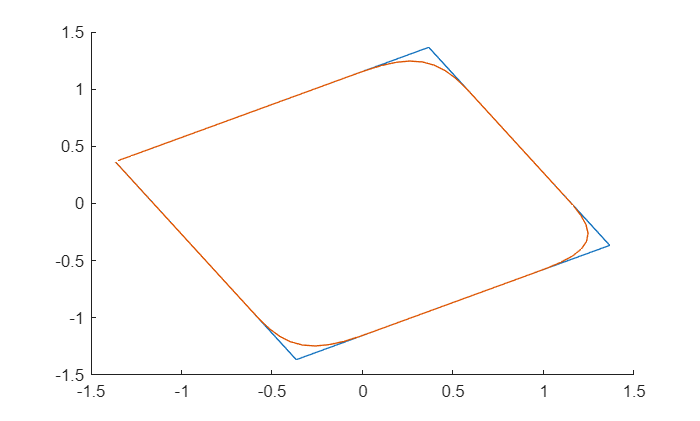

clf

via = SO2(30, 'deg') * [-1 1; 1 1; 1 -1; -1 -1]';
hold on
q0 = mstraj(via(:,[2 3 4 1])', [1,8], [], via(:,1)', 0.2, 0);
plot(q0(:,1), q0(:,2))
q1 = mstraj(via(:,[2 3 4 1])', [2,1], [], via(:,1)', 0.2, 2);
plot(q1(:,1), q1(:,2))

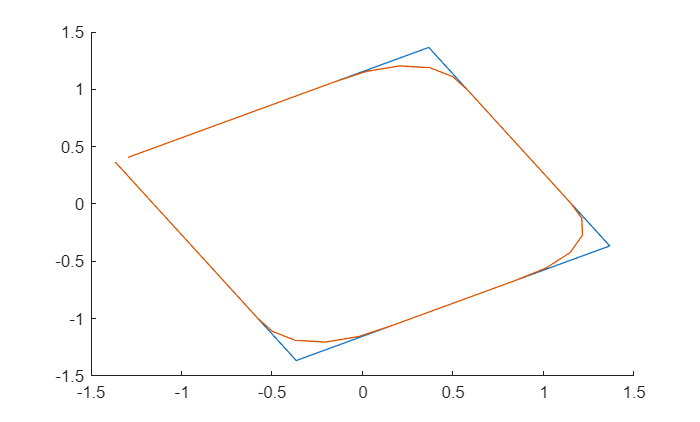


clf

via = SO2(30, 'deg') * [-1 1; 1 1; 1 -1; -1 -1]';
hold on
q0 = mstraj(via(:,[2 3 4 1])', [2,1], [], via(:,1)', 0.2, 0);
q1 = mstraj(via(:,[2 3 4 1])', [2,1], [], via(:,1)', 0.2, 1);
plot(q0(:,1), q0(:,2))
plot(q1(:,1), q1(:,2))


q2 = mstraj(via(:,[2 3 4 1])', [2,1], [], via(:,1)', 0.2, 2);

[numrows(q0) numrows(q2)]

ans =     28    80


## LAB 

### TASK 3.1

A=[0 0 0;0 0 0]

A =      0     0     0
     0     0     0


B=[0 0 1;0 pi/2 0]

B =          0         0    1.0000
         0    1.5708         0


C=[1 0 1;0 -pi 0]

C =     1.0000         0    1.0000
         0   -3.1416         0


D=[1 0 -0.5; 0 pi/2 0]

D =     1.0000         0   -0.5000
         0    1.5708         0


clf

via =  [A(1,:) A(2,:) ; B(1,:) B(2,:) ; C(1,:) C(2,:);D(1,:) D(2,:)]';
via(:,1)'

ans =      0     0     0     0     0     0


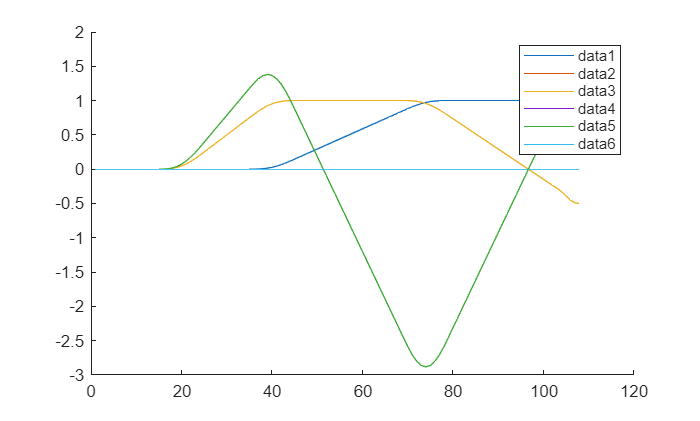

hold on
q0 = mstraj(via(:,[1 2 3 4])', [2,2,2,1,1,1], [], via(:,1)', 0.2, 2);
plot(q0);
legend

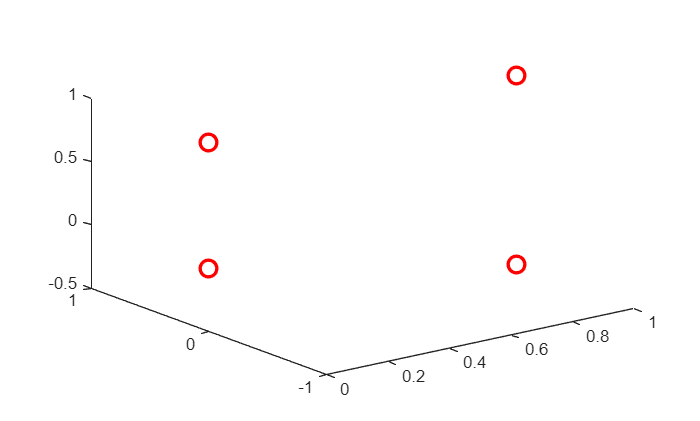


figure
Ts= SE3.empty();
for i =(1:1:length(q0(:,1)))
    Ts(i)=SE3([q0(i,1), q0(i,2),q0(i,3)]) * SE3.rpy(q0(i,4), q0(i,5), q0(i,6));
end

target_points = [A(1,:);B(1,:);C(1,:);D(1,:)]; 
plot3(target_points(:,1), target_points(:,2), target_points(:,3), 'ro', 'MarkerSize', 10, 'LineWidth', 2);

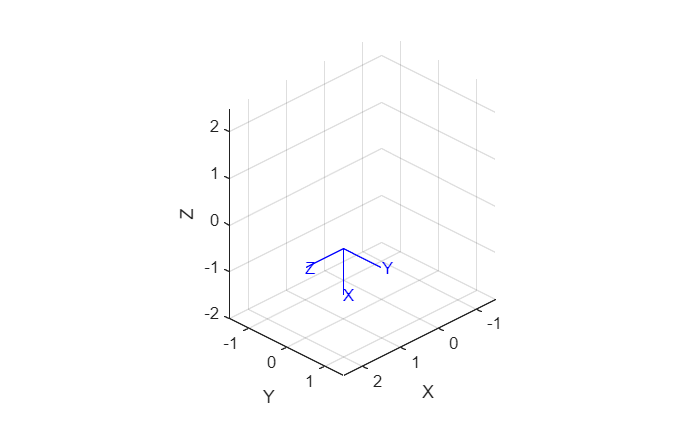


tranimate(Ts, 'view', [135, 30], 'dims', [-2 5 -2 5 -2 5])

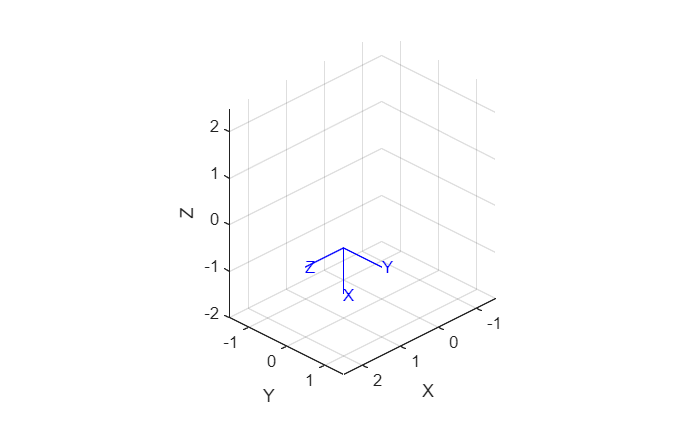

Ts.animate

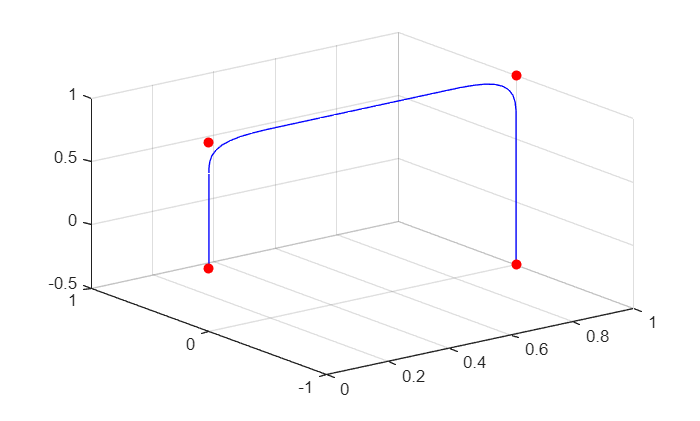

figure
plot3(q0(:,1), q0(:,2), q0(:,3), "-", Color="b")  % plot3 line
hold on                                            % retain existing plot
scatter3(A(1,1), A(1,2), A(1,3), 36, "r", "filled") % visible red dot
scatter3(B(1,1),B(1,2), B(1,3), 36, "r", "filled")
scatter3(C(1,1), C(1,2), C(1,3), 36, "r", "filled")
scatter3(D(1,1), D(1,2), D(1,3), 36, "r", "filled")
hold off
grid on
view(3)

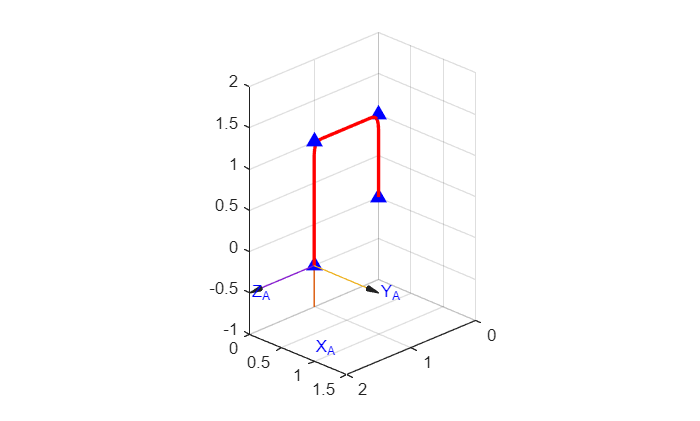


path_positions = Ts.t; 


figure;
hold on;
grid on;
view(135, 25);           
axis([0 2 0 1.5 -1 2]);   


waypoints = [A(1,:);B(1,:);C(1,:);D(1,:)];
plot3(waypoints(:,1), waypoints(:,2), waypoints(:,3), 'b^', 'MarkerFaceColor', 'b', 'MarkerSize', 8);
plot3(q0(:,1), q0(:,2), q0(:,3), 'r-', 'LineWidth', 2); 

hFrame = [];


for i = 1:length(Ts)
    
   
    if ~isempty(hFrame)
        delete(hFrame); 
    end
    
   
      
    hFrame = Ts(i).plot('frame', 'A', 'arrow', 'b', 'b'); 
    drawnow;
    pause(0.04); 
end

### TASK 3.2

%% clear the workspace variables and close all figures
clear all
clc
close all
%% Load the map
load map1
about map

map [double] : 100x100 (80.0 kB)


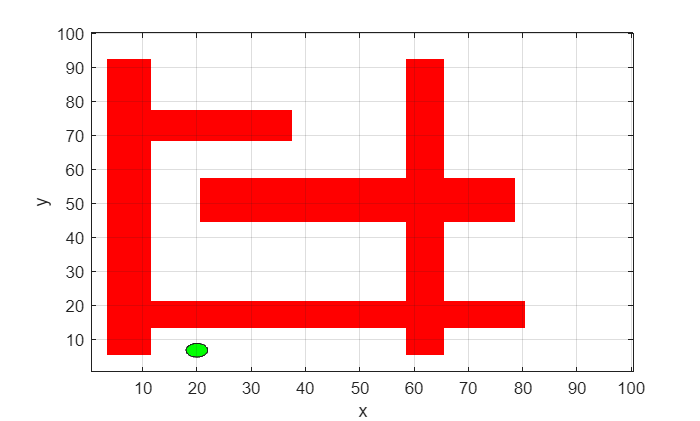

line =     80    50
   100    50


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


flag = logical
   0


flag = logical
   1


%% plot the map
plot(Bug2(map))
%% Initial position and heading of the robot
p_init=[50 30]; % [x,y]
%% Goal location of the robot 
p_goal=[20 5]; % [x,y]

%% Define the desired path 
path=[ p_init;
       15 30 ;
       15 65 ;
       50 65 ;
       50 100 ;
       90 100 ;
       90 60;
       95 60;
       90 0 ;
       50 0;
       50 10;
       20 10 ;
       p_goal
    ];

 
%%Genrate trajectory
QDMAX=[10];
TIME=[]; %axis speed limits
Q0= path(1,:); %initial axis coordinates
DT=0.2;
traj = mstraj(path, QDMAX, TIME, Q0, DT, 10);

%% Plot the path
%plot(traj);
obstacle=1; %0 when there is no door to block the way, 1 the door will be on
animatepath(traj,DT,obstacle)

### Task 3.3

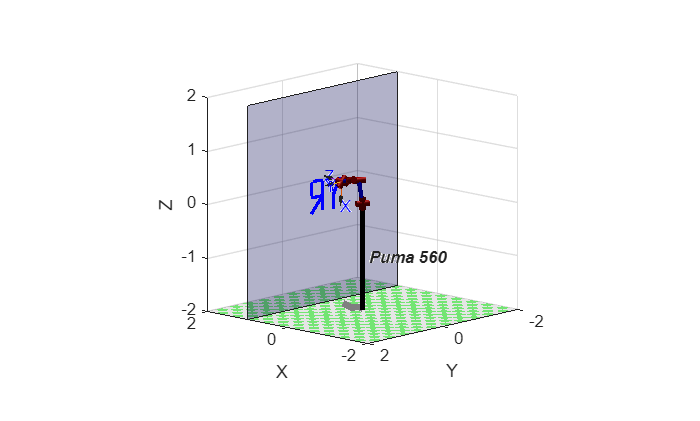

clear all
close all
clc
%% set up the enviroment
lim = [-2.0, 2.0, -2.0, 2.0, -2.0, 2.0]; % to define the limit of x,y,z
mdl_puma560     % to load the puma560 robot
p560.plot(qz,'workspace',lim)   % to draw the robot

% to define and to plot a wall 
a = 1;  % the wall is defined as ax+by+cz+d = 0 
b = 0;
c = 0;
d = -1;
wall = Wall(a,b,c,d,lim);  % to define the wall
wall.plotwall();           % to plot the wall


%% Define the desired path 
path=[0 0 0;
    0 0.3 0 ;
    0 0.3 0.3 ;
    0 0 0.3 ;
    0 0 -0.3 ;
    0 0 0;
    0 0.3 -0.3 ;
  
    ];

path_1=[0 0.3 -0.3;
    -0.1 0.3 -0.3;
    -0.1 -0.3 -0.3;
   0 -0.3 -0.3
  
    ];



path_2=[0 -0.3 -0.3;
   
    0 -0.3 0 ;
    0 -0.5 0.3 ;
   0 -0.3 0 ;
    0 -0.1 0.3 ;


    ];

 
%% Genrate trajectory
Q0= path(1,:); %initial axis coordinates
DT=0.2;
traj = mstraj(path, [0.1, 0.1,0.1], [], Q0, DT, 10);

Q0= path_1(1,:); %initial axis coordinates
DT=0.2;
traj_1 = mstraj(path_1, [0.5, 0.5,0.5], [], Q0, DT, 10);

Q0= path_2(1,:); %initial axis coordinates
DT=0.2;
traj_2 = mstraj(path_2, [0.4, 0.4,0.4], [], Q0, DT, 10);

%%send to robot
path=[traj;traj_1;traj_2];
Tp =SE3(0.6, 0, 0) *   SE3(path) * SE3.oa( [0 1 0], [1 0 0.1]);
q = p560.ikine6s(Tp);
plot_qtraj(q, wall, p560)

clear all
close all
clc
%% set up the enviroment
lim = [-2.0, 2.0, -2.0, 2.0, -2.0, 2.0]; % to define the limit of x,y,z
mdl_puma560     % to load the puma560 robot
p560.plot(qz,'workspace',lim)   % to draw the robot

% to define and to plot a wall 
a = cos(deg2rad(10));  % the wall is defined as ax+by+cz+d = 0 
b = 0;
c = sin(deg2rad(10));
d = -cos(deg2rad(10));
wall = Wall(a,b,c,d,lim);  % to define the wall
wall.plotwall();           % to plot the wall

%% place your trajectory generation code here
% 1) An example trajectory can be loaded from the 'q.mat' file


%% Define the desired path 
path=[0 0 0;
    0 0.3 0 ;
    0 0.3 0.3 ;
    0 0 0.3 ;
    0 0 -0.3 ;
    0 0 0;
    0 0.3 -0.3 ;
  
    ];

path_1=[0 0.3 -0.3;
    -0.1 0.3 -0.3;
    -0.1 -0.3 -0.3;
   0 -0.3 -0.3
  
    ];



path_2=[0 -0.3 -0.3;
    0 -0.3 0 ;
    0 -0.5 0.3 ;
    0 -0.3 0 ;
    0 -0.1 0.3 ;
    ];

R=roty(10, 'deg')

R =     0.9848         0    0.1736
         0    1.0000         0
   -0.1736         0    0.9848


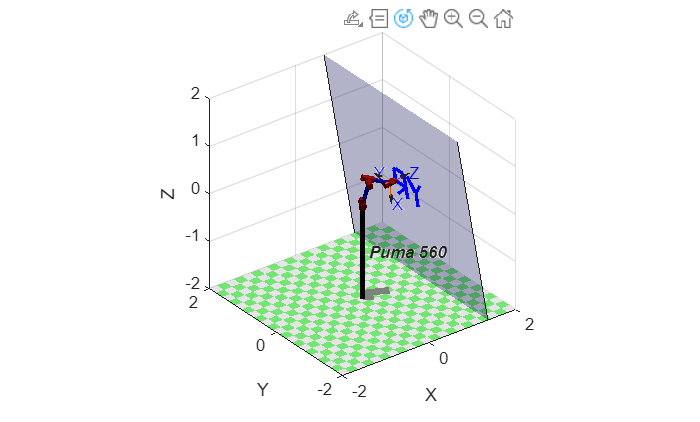

path=path*R;
path_1=path_1*R;
path_2=path_2*R;
%% Genrate trajectory
Q0= path(1,:); %initial axis coordinates
DT=0.2;
traj = mstraj(path, [0.1, 0.1,0.1], [], Q0, DT, 10);

Q0= path_1(1,:); %initial axis coordinates
DT=0.2;
traj_1 = mstraj(path_1, [0.5, 0.5,0.5], [], Q0, DT, 10);

Q0= path_2(1,:); %initial axis coordinates
DT=0.2;
traj_2 = mstraj(path_2, [0.4, 0.4,0.4], [], Q0, DT, 10);

%%send to robot
path=[traj;traj_1;traj_2];
Tp =SE3(0.6, 0, 0) *   SE3(path) * SE3.oa( [0 1 0], [1 0 0.1]);
q = p560.ikine6s(Tp);
plot_qtraj(q, wall, p560)

### Task 3.4

function path=generate_path(init,n_steps,delta)
    path=[init]
    for i=1:2:n_steps*2
        i
        path = [path;init+[(i-1)*delta, 0, 0]; init + [(i-1)*delta, 0, 4];init + [(i)*delta, 0, 4];init + [(i)*delta, 0, 0];];
    end
end

clear all
clc
close all
addpath(genpath('./'));



%% Initial position and heading of the robot
p_init=[-5,2,0]; 
p_start=[-1,2,1]

p_start =     -1     2     1


%% Goal location of the robot 
p_goal=[22,2,0]; 


%% Define the desired path 
path=[p_init;generate_path(p_start,4,3);p_goal]

path =     -1     2     1


i = 1

i = 3

i = 5

i = 7

path =     -5     2     0
    -1     2     1
    -1     2     1
    -1     2     5
     2     2     5
     2     2     1
     5     2     1
     5     2     5
     8     2     5
     8     2     1
    11     2     1
    11     2     5
    14     2     5
    14     2     1
    17     2     1


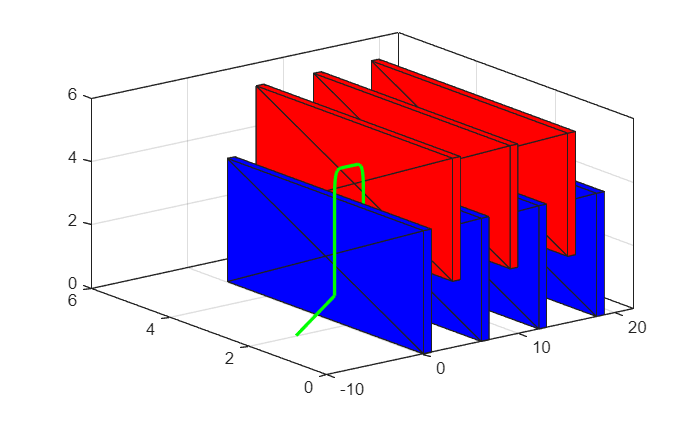



 
%%Genrate trajectory
QDMAX=[1];
TIME=[]; %axis speed limits
Q0= path(1,:); %initial axis coordinates
DT=0.2;
traj = mstraj(path, QDMAX, TIME, Q0, DT, 10);

%%Plot the path
plot3(traj(:,1), traj(:,2), traj(:,3), 'g-', 'LineWidth', 2); 

% map1.txt and map2.txt are the complex enviroments
map = load_map('maps/map1.txt', 0.1, 2, 0.25);
plot_path(map);
grid on
box on

clear all
clc
close all
addpath(genpath('./'));


%% Initial position and heading of the robot
p_init=[5,1,0]; 

%% Goal location of the robot 
p_goal=[5,20,2]; 

%% Define the desired path 
path=[p_init;
    5,1,3.5;
    5,13,3.5;
    5,13,4;
    5,16,4;
    p_goal]

path =     5.0000    1.0000         0
    5.0000    1.0000    3.5000
    5.0000   13.0000    3.5000
    5.0000   13.0000    4.0000
    5.0000   16.0000    4.0000
    5.0000   20.0000    2.0000


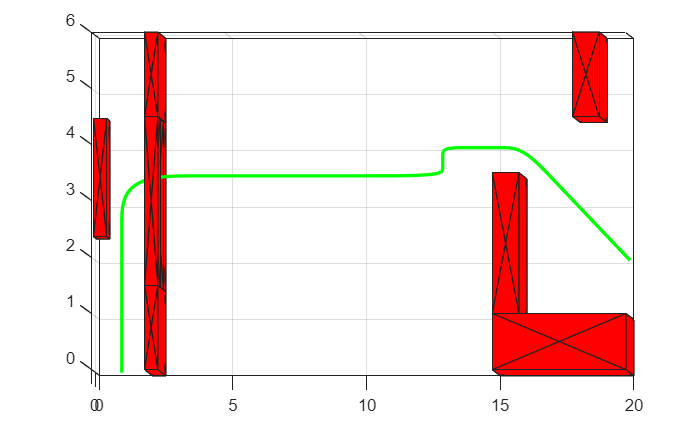


%%Genrate trajectory
QDMAX=[1];
TIME=[]; %axis speed limits
Q0= path(1,:); %initial axis coordinates
DT=0.2;
traj = mstraj(path, QDMAX, TIME, Q0, DT, 10);

%%Plot the path
plot3(traj(:,1), traj(:,2), traj(:,3), 'g-', 'LineWidth', 2); 


% map1.txt and map2.txt are the complex enviroments
map = load_map('maps/map2.txt', 0.1, 2, 0.25);
plot_path(map);
grid on
box on

close all

clear all

clc

%%

ptCloud = pcread('fountain.ply');

pcshow(ptCloud);

tw = Twist('R', [1 0 0], [0 0 0])

tw.T(0.3)

tw = Twist('T', [0 1 0])

tw.T(2)

X = transl(3, 4, -4);

angles = [0:0.3:15];

tw = Twist('R', [0 1 1], [2 3 2], 0.8);

clf

tranimate( @(theta) tw.T(theta) * X, angles, ...

     'length', 0.5, 'retain', 'rgb', 'notext');

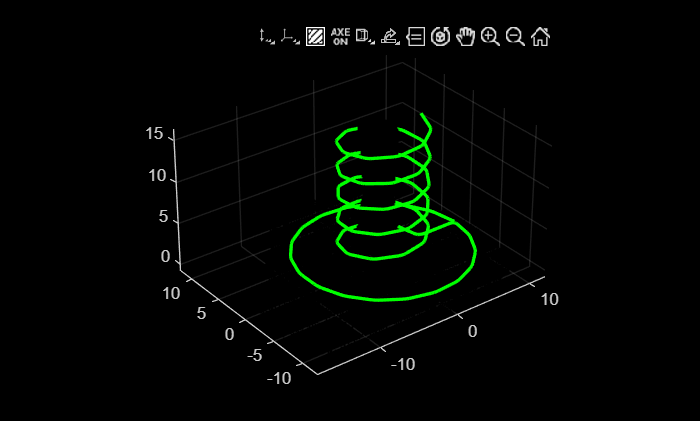

close all
clear all
clc
ptCloud = pcread('fountain.ply');
pcshow(ptCloud);
% Fountain Parameters
center = [0 0 1];
radius = 4+1;
turns = 5;
height = 16;
via_n = 50;


% Generating via points on a helix around the fountain
theta = linspace(0, turns * 2 * pi, via_n)'; % Generate angles for every via point (step)
z = linspace(center(3), height, via_n)'; % Generate height for every via point (step)


via_1 = [center(1) + radius*cos(theta), center(2)+ radius*sin(theta), z];

% Fountain Parameters
center = [0 0 1];
radius = 10;
turns = 1;
height = 1;
via_n = 20;


% Generating via points on a helix around the fountain
theta = linspace(0, turns * 2 * pi, via_n)'; % Generate angles for every via point (step)
z = linspace(center(3), height, via_n)'; % Generate height for every via point (step)

via_2=[center(1) + radius*cos(theta), center(2)+ radius*sin(theta), z];


via=[via_2;via_1];
QDMAX=[0.5,0.5,0.5]; %axis speed limits
Q0= via(1,:); %initial axis coordinates
DT=0.2;
traj = mstraj(via, QDMAX, [], Q0, DT, 10);
hold on
plot3(traj(:,1), traj(:,2), traj(:,3), 'g-', 'LineWidth', 2);
hold off

function path=gen_spiral( radius, turns,height,n,C,R_a)

    R = rpy2r(R_a(1),R_a(2),R_a(3));
    theta = linspace(0, turns * 2 * pi, n)'; % Generate angles for every via point (step)
    z = linspace(0, height,n)'; % Generate height for every via point (step)
    points = [ radius*cos(theta),+ radius*sin(theta), z];
    path=(R * points')' + C;
   
end

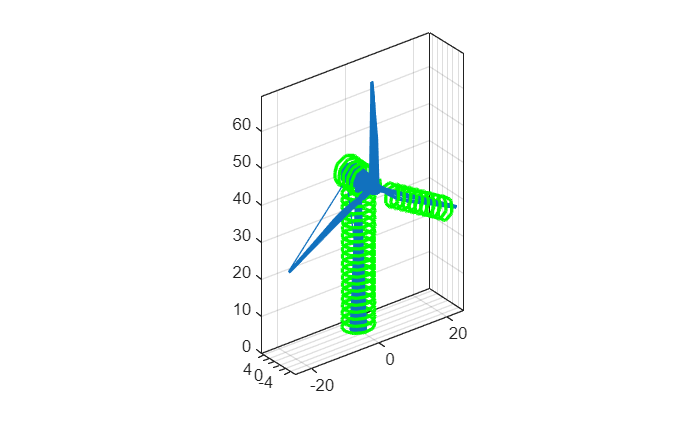

close all
clear all
clc
load('Points10.mat') %All
X=X/10;
Y=Y/10;
Z=Z/10;        
xyz=[X Y Z];
plot3(X,Y,Z);
grid on
box on
axis equal


via_1=gen_spiral( 4,20,38,200,[0,0,0],[0,0,0]);
via_2=gen_spiral( 4,5,8,40,[0,5,41],[pi/2, 0, 0]);
via_3=gen_spiral( 3,10,20,60,[5, -5, 37],[-pi/3, pi, 3*pi/2]);






via=[via_1;via_2;via_3];
QDMAX=[0.5,0.5,0.5]; %axis speed limits
Q0= via(1,:); %initial axis coordinates
DT=0.2;
traj = mstraj(via, QDMAX, [], Q0, DT, 10);
hold on
plot3(traj(:,1), traj(:,2), traj(:,3), 'g-', 'LineWidth', 2);
hold off